clear
clf

f = [1; 2; 2; 4];
A = zeros(4, 4);

% The A matrix contains the values of f according to a third degree
% polynomial
for t_data = 1:4
    A(t_data, :) = [1, t_data, t_data^2, t_data^3];
end

A

A =      1     1     1     1
     1     2     4     8
     1     3     9    27
     1     4    16    64



% QR decomposition to find x
[Q,R] = qr(A);
x = R \ (Q' * f)

x =    -4.0000
    8.0000
   -3.5000
    0.5000


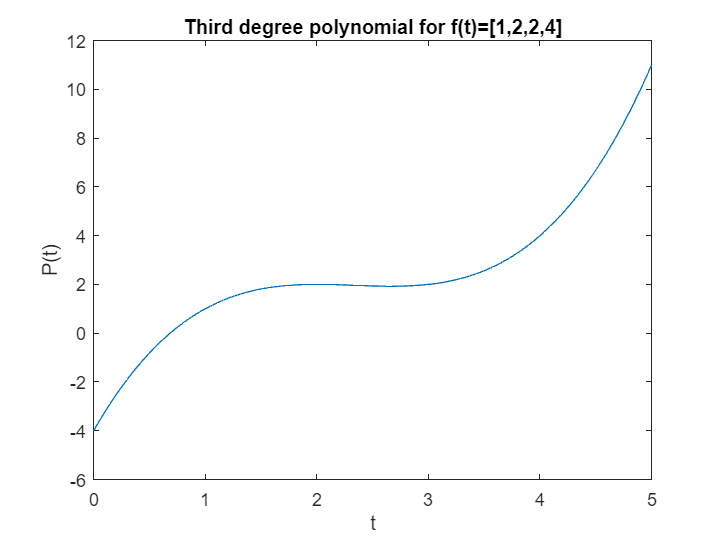


% Third degree polynomial
P = @(t) x(1) + x(2)*t + x(3)*t.^2 + x(4)*t.^3;

% Plotting t and function values
t_values = linspace(0, 5, 100);
P_values = P(t_values);

plot(t_values, P_values);
title('Third degree polynomial for f(t)=[1,2,2,4]')
xlabel('t')
ylabel('P(t)')

clear
clf

f = [1; 2; 2; 4; 5];
A = zeros(5, 4);

for t_data = 1:5
    A(t_data, :) = [1, t_data, t_data^2, t_data^3];
end

A

A =      1     1     1     1
     1     2     4     8
     1     3     9    27
     1     4    16    64
     1     5    25   125



[Q,R] = qr(A);

x = R \ (Q' * f)

x =     0.8000
    0.1429
    0.1429
   -0.0000


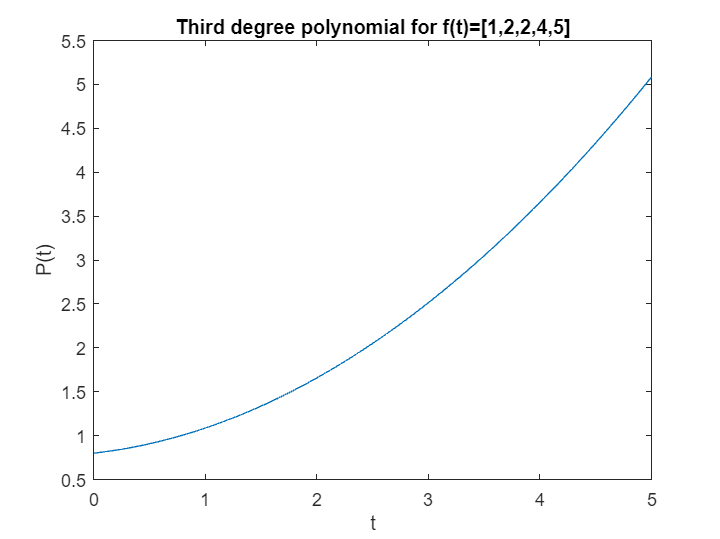


P = @(t) x(1) + x(2)*t + x(3)*t.^2 + x(4)*t.^3;

t_values = linspace(0, 5, 100);
P_values = P(t_values);

plot(t_values, P_values);
title('Third degree polynomial for f(t)=[1,2,2,4,5]')
xlabel('t')
ylabel('P(t)')